s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




Gs = 1.06/(s*(s+1)*(s+2))

Gs =
 
        1.06
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.



Gsmf = feedback(Gs, 1)

Gsmf =
 
            1.06
  ------------------------
  s^3 + 3 s^2 + 2 s + 1.06
 
Continuous-time transfer function.



pole(Gsmf)

ans =   -2.3386 + 0.0000i
  -0.3307 + 0.5864i
  -0.3307 - 0.5864i


O polo dominante é o mais perto do eixo imaginario:

**Usaremos as formulas:**

 Y = 𝜔𝑛:

            Y = sqrt(raizReal^2+raizImaginaria^2 )

 X = ζ :

           X = raizReal/Y

raizReal = 0.3307

raizReal = 0.3307

raizImaginaria = 0.5864

raizImaginaria = 0.5864

Y = sqrt(raizReal^2+raizImaginaria^2 )

Y = 0.6732

X = raizReal/Y

X = 0.4912

calcuremos a constante de erro estatico (Kv) para o sistema:

    syms s declara s como uma variavel 

    precisa declara a função encontrada la em Gs

   ** --> se o sistema é do tipo 0 (posição) DEGRAU [zero polos na origem]:**

            usa: Fx = (F(p));  para achar o Kv

                       erro = 1/1+Kv

                       Kvc = (1/erro)-1

    **--> se o sistema é do tipo 1 (velocidade) RAMPA [um polos na origem]:**

            usa: Fx = p*(F(p));    para achar o Kv

                       erro = 1/Kv

                        Kvc = (1/erro)

     **--> se o sistema é do tipo 2 (aceleração) [dois polos na origem]:**

            usa: Fx = P^2*(F(p));    para achar o Kv

                        erro = 1/Kv

                         Kvc = (1/erro)

syms p;
Fx = p*(1.06/(p^3+3*p^2+2*p))

$$Fx = \frac{53\,p}{50\,\left(p^{3}+3\,p^{2}+2\,p\right)}$$

Kv = limit(Fx, p, 0) %vpa retorna o decimal da resposta

$$Kv = \frac{53}{100}$$

Kv1 = 53/100

Kv1 = 0.5300

Determinar quanto a constante de erro deve ser aumentada para um erro não ultrapasse a especificações do problema:

    erro = especificado pelo problema

    KvC = erro a ser determinado dado o erro especificado

erro = 0.2

erro = 0.2000

KvC = (1/erro)

KvC = 5

Calculo do Beta:

B = KvC/Kv1

B = 9.4340

B = ceil(B) % função ceil arredonda pra cima

B = 10

determinar o polo e o zero do compensador, escolhendo um proximo da origem

    Zero escolhido = -0,05

zero = -0.05

zero = -0.0500

Calculo de T dado o zero escolhido:

Relação T e zero

        1/zero = T

T = 1/(zero)*-1

T = 20

Calculo do polo so compensador

    dado por: poloCompensador = -1/(B*T)

        Onde B = Beta

                T =  T calculado atraves do zero

poloCompensador = -1/(B*T)

poloCompensador = -0.0050

podemos achar a função de transferemcia do controlador:

    Gcontrolador = Kc(s+ zero/s+poloCompensador)

num = s+ zero*-1

num =
 
  s + 0.05
 
Continuous-time transfer function.



den = s+ poloCompensador*-1

den =
 
  s + 0.005
 
Continuous-time transfer function.



Falta Kc que a primeira vista consideramos 1, esse valor pode ser alterado se o valor pode ser alterado se o zero escolhido não tenha sido suficientemente perto da origem

Por isso considerase o Kc igual a 1 e se plota o sistema, juntamento com o sistema não controlado, dependendo do que o problema pedir pode se alterar esse polo, observando as raizes e o amortecimento, ambas precisam ser coincidentes, a frequencia natural pode diminuir ou aumentar, dependendo aonde vc insira o novo polo

A pergunta a ser respondida é:

    "o quão proximo da origem precisa ser esse zero do compensador?"

        --> isso depende muito do sistema

        --> dos polos dominantes em malha fechada

Kc = 1;
Gcontrolador = (num/den)

Gcontrolador =
 
  s + 0.05
  ---------
  s + 0.005
 
Continuous-time transfer function.



Gcontrolador = Kc*(Gcontrolador)

Gcontrolador =
 
  s + 0.05
  ---------
  s + 0.005
 
Continuous-time transfer function.




SistemaMalhaFechada = feedback(Gcontrolador * Gs, 1)

SistemaMalhaFechada =
 
                 1.06 s + 0.053
  --------------------------------------------
  s^4 + 3.005 s^3 + 2.015 s^2 + 1.07 s + 0.053
 
Continuous-time transfer function.



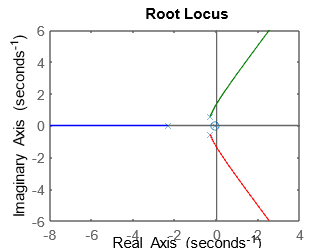

rlocus(SistemaMalhaFechada)

Outro metodo de encontra o Kc é pela magnitude do lugar das raizes 

para isso se precisa dos polos de malha fechada do novo lugar das raizes:

pole(SistemaMalhaFechada)

ans =   -2.3339 + 0.0000i
  -0.3082 + 0.5657i
  -0.3082 - 0.5657i
  -0.0547 + 0.0000i


Se escolhe o polo dominante ( aquele que tem tanto no positivo quanto negatico mais proximo da origem)

raizRealSisMalhaFechada = -0.3082

raizRealSisMalhaFechada = -0.3082

raizImagSisMalhaFechada = 0.563*j

raizImagSisMalhaFechada = 0.0000 + 0.5630i

raizezJuntas = raizRealSisMalhaFechada + raizImagSisMalhaFechada

raizezJuntas = -0.3082 + 0.5630i

E com os polos substituimos na formula para encontrar a nova KcC

KcC=1/abs(evalfr(Gcontrolador*Gs, raizezJuntas))

KcC = 0.9942

Logo o compensador de atraso é dado por:

GcompensadorAtraso = KcC*(Gcontrolador)

GcompensadorAtraso =
 
  0.9942 s + 0.04971
  ------------------
      s + 0.005
 
Continuous-time transfer function.



calculamos a funçaõ de transferencia do sistema com o controlador encontrado:

Gmf = (GcompensadorAtraso * Gs)/(1+(GcompensadorAtraso * Gs))

Gmf =
 
                1.054 s^5 + 3.219 s^4 + 2.282 s^3 + 0.1167 s^2 + 0.0005269 s
  ----------------------------------------------------------------------------------------
  s^8 + 6.01 s^7 + 13.06 s^6 + 13.18 s^5 + 7.34 s^4 + 2.322 s^3 + 0.1168 s^2 + 0.0005269 s
 
Continuous-time transfer function.



Gmf = minreal(Gmf)

Gmf =
 
                 1.054 s + 0.05269
  -----------------------------------------------
  s^4 + 3.005 s^3 + 2.015 s^2 + 1.064 s + 0.05269
 
Continuous-time transfer function.



pole(Gmf)

ans =   -2.3325 + 0.0000i
  -0.3089 + 0.5632i
  -0.3089 - 0.5632i
  -0.0548 + 0.0000i


stepinfo(Gmf)

Calculando o erro do sistema compensado:

syms p;
Fx = 1.054*p+0.005/(p^4+3.005*p^3+2.015+1.064*p+0.5269)

$$Fx = \frac{527\,p}{500}+\frac{1}{200\,\left(p^{4}+\frac{601\,p^{3}}{200}+\frac{133\,p}{125}+\frac{25419}{10000}\right)}$$

Kv = limit(Fx, p, 0) %vpa retorna o decimal da resposta

$$Kv = \frac{50}{25419}$$

Kv = 50/25419

Kv = 0.0020